# Introduction: Mass-Spring-Damper System

% Transfer Function
m = 1;
b = 10;
k = 20;

s = tf('s');
sys = 1/(m*s^2+b*s+k);

Ts = 1/100;

% Discrete Transfer Function
sys_d = c2d(sys,Ts,'zoh')


sys_d =
 
  4.837e-05 z + 4.678e-05
  -----------------------
  z^2 - 1.903 z + 0.9048
 
Sample time: 0.01 seconds
Discrete-time transfer function.
Model Properties


% Continuous-time State-Space Model
A = [0       1;
    -k/m   -b/m];

B = [  0;
    1/m];

C = [1 0];

D = [0];

Ts = 1/100;

% Discrete-time State-Space Model
sys = ss(A,B,C,D);
sys_d = c2d(sys,Ts,'zoh')


sys_d =
 
  A = 
             x1        x2
   x1     0.999  0.009513
   x2   -0.1903    0.9039
 
  B = 
              u1
   x1  4.837e-05
   x2   0.009513
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Sample time: 0.01 seconds
Discrete-time state-space model.


% Stability and Transient Response
numDz = 1;
denDz = [1 -0.3 0.5];
sys = tf(numDz,denDz,-1); % the -1 indicates that the sample time is undetermined

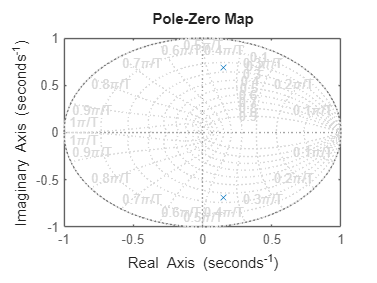

% Pole-Zero Map
figure(1)
pzmap(sys)
axis([-1 1 -1 1])
zgrid

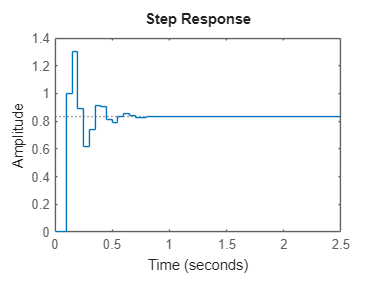

% Step Response Plot
sys_d2 = tf(numDz, denDz, 1/20);
figure(2)
step(sys_d2, 2.5)

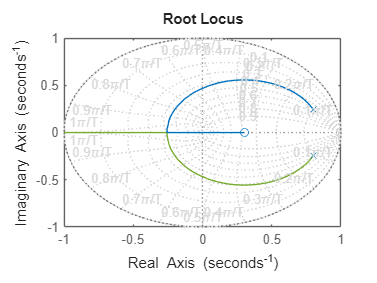

% Discrete-time Root Locus Diagram
numDz = [1 -0.3];
denDz = [1 -1.6 0.7];
sys = tf(numDz,denDz,-1);

figure(3)
rlocus(sys)
axis([-1 1 -1 1])

zeta = 0.4;
Wn = 0.3;
zgrid(zeta,Wn)

## Cruise Control

% Discrete-time Transfer Function
m = 1000;
b = 50;
u = 500;

s = tf('s');
P_cruise = 1/(m*s+b);

Ts = 1/50;

dP_cruise = c2d(P_cruise,Ts,'zoh')


dP_cruise =
 
  1.999e-05
  ---------
  z - 0.999
 
Sample time: 0.02 seconds
Discrete-time transfer function.
Model Properties


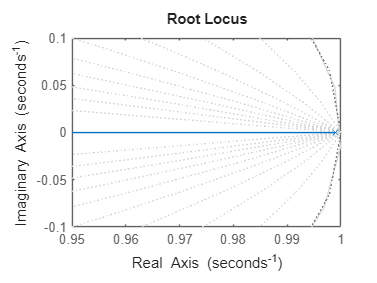

% Root Locus Diagram in the z-Plane
Wn = 0.0072;
zeta = 0.6;

rlocus(dP_cruise)
zgrid(zeta, Wn)
axis ([-1 1 -1 1])
axis ([0.95 1 -.1 .1])

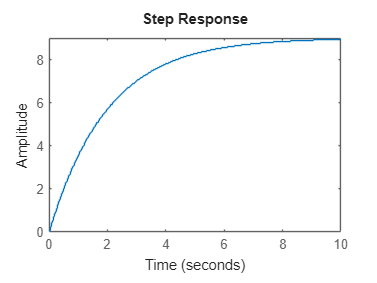

% Closed-loop Step Response
K = 451.1104;
sys_cl = feedback(K*dP_cruise,1);
r = 10;
figure
step(r*sys_cl,10);

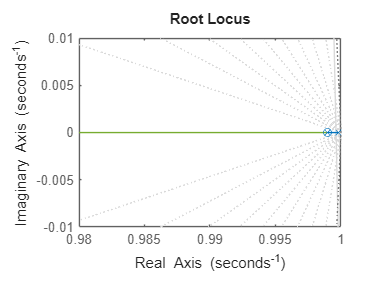

% Compenstation Digital Controller Root Locus
m = 1000;
b = 50;
u = 500;

s = tf('s');
P_cruise = 1/(m*s+b);
Ts = 1/50;
dP_cruise = c2d(P_cruise,Ts,'zoh');

z = tf('z',Ts);
C = 0.2*(z - 0.999)/(z - 0.9998);

Wn = 0.0072;
zeta = 0.6;

rlocus(C*dP_cruise)
zgrid(zeta, Wn)
axis([0.98 1 -0.01 0.01])

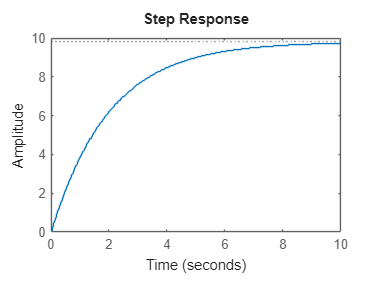

% Step Response of the Closed-loop System with the Compensation Controller
K = 2.4454e+03;
sys_cl = feedback(K*C*dP_cruise,1);
r = 10;
step(r*sys_cl,10);

## Motor Speed Control

% The continuous Transfer Function
J = 0.01;
b = 0.1;
K = 0.01;
R = 1;
L = 0.5;
s = tf('s');
P_motor = K/((J*s+b)*(L*s+R)+K^2);
zpk(P_motor)


ans =
 
           2
  -------------------
  (s+9.997) (s+2.003)
 
Continuous-time zero/pole/gain model.
Model Properties


% The Discrete Transfer Function
Ts = 0.05;
dP_motor = c2d(P_motor,Ts,'zoh');
zpk(dP_motor)


ans =
 
  0.0020586 (z+0.8189)
  ---------------------
  (z-0.9047) (z-0.6066)
 
Sample time: 0.05 seconds
Discrete-time zero/pole/gain model.
Model Properties


% The closed-loop step Response
sys_cl = feedback(dP_motor,1);
[y,t] = step(sys_cl,12);
stairs(t,y);
xlabel('Time (s)')
ylabel('Velocity (rad/s)')
title('Stairstep Response: Original')

% The Closed-loop Step Response with Original PID Controller
Kp = 100;
Ki = 200;
Kd = 10;

C = Kp + Ki/s + Kd*s;
dC = c2d(C,Ts,'tustin')


dC =
 
  505 z^2 - 790 z + 305
  ---------------------
         z^2 - 1
 
Sample time: 0.05 seconds
Discrete-time transfer function.
Model Properties


sys_cl = feedback(dC*dP_motor,1);
[x2,t] = step(sys_cl,12);
stairs(t,x2)
xlabel('Time (seconds)')
ylabel('Velocity (rad/s)')
title('Stairstep Response: with PID controller')

rlocus(dC*dP_motor)
axis([-1.5 1.5 -1 1])
title('Root Locus of Compensated System')

% The closed-loop step Response with PID + Conpensator Controller
z = tf('z',Ts);
dC = dC/(z+0.82);
rlocus(dC*dP_motor);
axis([-1.5 1.5 -1 1])
title('Root Locus of Compensated System');


sys_cl = feedback(0.8*dC*dP_motor,1);
[x3,t] = step(sys_cl,8);
stairs(t,x3)
xlabel('Time (seconds)')
ylabel('Velocity (rad/s)')
title('Stairstep Response: with Modified PID controller')

## DC Motor Position

% Creating a sampled-date model of the plant
J = 3.2284E-6;
b = 3.5077E-6;
K = 0.0274;
R = 4;
L = 2.75E-6;
s = tf('s');
P_motor = K/(s*((J*s+b)*(L*s+R)+K^2));
zpk(P_motor)


ans =
 
         3.0862e+09
  ------------------------
  s (s+1.454e06) (s+59.23)
 
Continuous-time zero/pole/gain model.
Model Properties



Ts = 0.001;
dP_motor = c2d(P_motor, Ts, 'zoh');
zpk(dP_motor)


ans =
 
  0.0010389 (z+0.9831) (z+9.256e-07)
  ----------------------------------
          z (z-1) (z-0.9425)
 
Sample time: 0.001 seconds
Discrete-time zero/pole/gain model.
Model Properties



dP_motor = minreal(dP_motor,0.001);
zpk(dP_motor)


ans =
 
  0.0010389 (z+0.9831)
  --------------------
    (z-1) (z-0.9425)
 
Sample time: 0.001 seconds
Discrete-time zero/pole/gain model.
Model Properties



sys_cl = feedback(dP_motor,1);
[x1,t] = step(sys_cl,.5);
stairs(t,x1)
xlabel('Time (seconds)')
ylabel('Position (radians)')
title('Stairstep Response: Original')
grid

% Root locus design
Ts = 0.25; % desired sample time
dP_motor_d = c2d(dP_motor, Ts); % convert dP_motor to discrete

dist_cl = feedback(dP_motor_d, C);
[x2,t] = step(dist_cl, Ts);
stairs(t, x2)
xlabel('Time (seconds)')
ylabel('Position (rad)')
title('Stairstep Disturbance Response with Compensation')
grid on

         